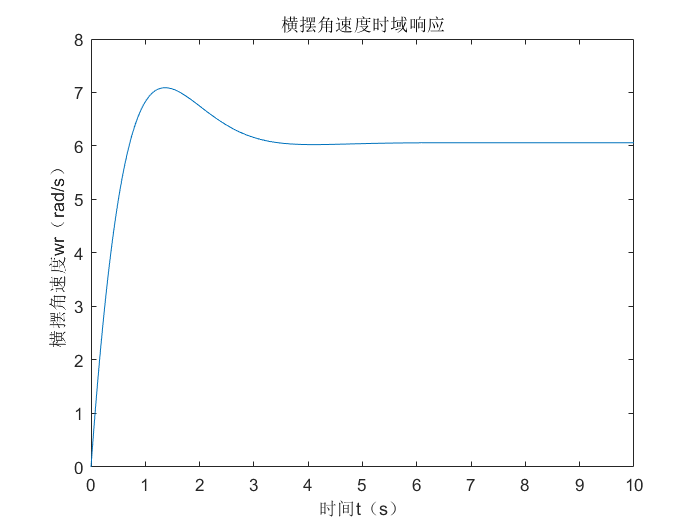

% 参数导入
m=1150;
r=0.287;
lf=1.4;
lr=1.26;
kf=-18500;
kr=-22500;
Iz=1850;
l=lf+lr;

v=30;
delta=1;
K=m/l^2*(lf*kf-lr*kr)/(kr*kf);
R=(1+K*v^2)*l/delta;

% 绘制0~10s横摆角速度时域响应
t=0:0.01:10;
wr0=1/(1+K*v^2)*v/l*delta;
% c=m*v*(lf*kf-lr*kr)+l^2*kf*kr/v;
m_=m*v*Iz;
w0=l/v*sqrt(kr*kf*(1+K*v^2)/(m*Iz));
h=-(m*(lf^2*kf+lr^2*kr)+Iz*(kf+kr));
sigma=h/(2*w0*m_);
w=w0*sqrt(1-sigma^2);
fai=atan(sqrt(1-sigma^2)/(m*v*lf*w0/l/kr+sigma));
wr=wr0*(1+sqrt(((-m*v*lf/(l*kr))^2*w0^2+2*m*v*lf*sigma*w0/(l*kr)+1)/(1-sigma^2)).*exp(-sigma*w0.*t).*sin(w.*t+fai));
plot(t,wr);
title('横摆角速度时域响应')
xlabel('时间t（s）')
ylabel('横摆角速度wr（rad/s）')

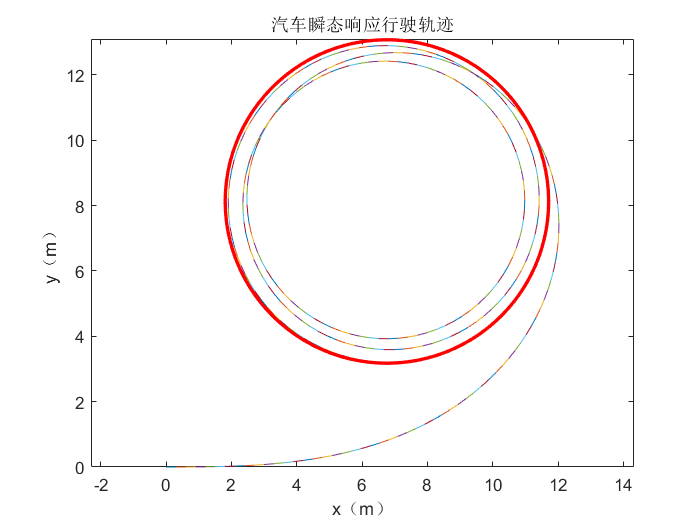

% 汽车瞬态响应行驶轨迹
tempR=v./wr;
x=0;y=0;
theta=0;
figure
for i=1:1001
    if i<800
    theta=theta+wr(i)*0.01;
    lastx=x;
    lasty=y;
    x=x+tempR(i)*wr(i)*0.01*cos(theta+wr(i)*0.01/2);
    y=y+tempR(i)*wr(i)*0.01*sin(theta+wr(i)*0.01/2);
    plot([lastx,x],[lasty,y])
    axis equal
    hold on
    pause(0.05);
    % 接近稳态后，用粗红实线画出
    else
    theta=theta+wr(i)*0.01;
    lastx=x;
    lasty=y;
    x=x+tempR(i)*wr(i)*0.01*cos(theta+wr(i)*0.01/2);
    y=y+tempR(i)*wr(i)*0.01*sin(theta+wr(i)*0.01/2);
    plot([lastx,x],[lasty,y],'r-',"LineWidth",2)
    axis equal
    hold on
    pause(0.01);        
    end
end
title('汽车瞬态响应行驶轨迹')
xlabel('x（m）')
ylabel('y（m）')
hold off